## Load Data

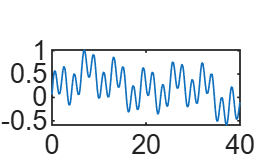

% Sinusoid data
load('Isolated_Flywheel_action.mat')
y = angular_velocity.data;
u_current = dc_current.data;
u = stim_input_1;
%u = u_current;
N = size(t,2);
end_train = floor(N*1/2);
%{
y = y(1:end_train);
t = t(1:end_train);
N = size(t,2);
%}
figure; 
plot(t,u)

y = y(3:end);
u = u(3:end);
N = N-2;
t = t(3:end);
clearvars -except y N t u

## Apply PEM

theta0 = [-5 1000 0.2]';
theta = theta0;
lambda = 0.1;
maxiter = 10000;
p = 3;
h = 0.01;

% initialize
converged = false;
maxiter_reached = false;
iter = 1;
while ~converged && ~maxiter_reached 

    %%%%%% YOUR CODE HERE %%%%%%

    [Abar,Bbar, C,x0] = theta2matrices(theta, h);
    [yhat, xhat] = simsystem_y_as_vec(Abar, Bbar, C, x0, u);
    E = y - yhat;
    psi = psi_fun(xhat, x0, Abar, h, u);
    N_E = length(E);
    J = 2/N_E * psi' * E; % Jacobian
    N_H = size(psi,1);
    H = 2/N_H * (psi' * psi); % Hessian

    invLM = (H + lambda * eye(p))\eye(p); %Levenberg-Marquardt singularity inverse
    theta_new = theta - invLM * J;

    
    % Check convergence
    if norm(theta_new - theta) < 1e-6
        converged = true; 
    elseif iter == maxiter 
        maxiter_reached = true; 
        warning('Maximum iterations reached'); 
    end
    theta = theta_new; 
    iter = iter + 1;
end   


## Evaluate

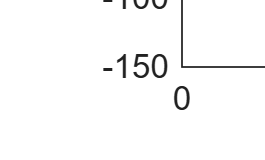

[yhat, xhat] = simsystem_y_as_vec(Abar, Bbar, C, x0, u);

figure;
hold on
plot(t,y);
plot(t,yhat);
legend('True', 'Estimated');

## PEM (functions)

function [A, B, C,x0] = theta2matrices(theta, h)
% Converts theta into matrices for a full parameterisation with n = 3, l =
% 2
% Function INPUT
% theta     Parameter vector (vector of size: according to the realization)
%
% Function OUTPUT
% Abar      System matrix A (matrix of size n x n)
% Bbar      System matrix B (matrix of size n x m)
% C         System matrix C (matrix of size l x n)
% D         System matrix D (matrix of size l x m)
% x0        Initial state (vector of size n x one)

%%%%%% YOUR CODE HERE %%%%%%
a1 = theta(1); a2 = theta(2);
x0 = theta(3);

A = 1 + h*a1;
B = a2*h;
C = 1;
end

function psi = psi_fun(xhat, x0, Abar, h, u)
C = 1;

% Dimensions
l = 1;

% Derivative Definitions
dAbar1 = h;

dBbar2 = h;

dx03 = 1;

N = size(xhat,1); 
p = 3; % 11 sub-parameters of theta
xhat = xhat'; % x coming in is Nxn, now is nxN

dy = zeros(l,p);
psi = zeros((N-1)*l,p);

% First iteration
dx1 = dAbar1 * x0;

dx=[dx1 0 dx03];
for k = 2:N % xhat is 0 - N-1, 
    % dy / psi update
    for i = 1 : p
        dy(:,i) = C * dx(i);
    end
    psi((k-l)*l+1:(k-l)*l+l,:) = -dy; % psi is relative to -dyhat

    % dx update
    % A parameters
    dx(:,1) = Abar * dx(1) + dAbar1 * xhat(k);
    
    % B parameter
    dx(:,2) = Abar * dx(2) + dBbar2 * u(k);

    % x0 parameters
    dx(:,3) = Abar * dx(3);

end
 %psi = [zeros(l,p) ; psi]; % How to deal with dyhat0?
end

function [y,x] = simsystem_y_as_vec(A, B, C, x0, u)
% Instructions:
% Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% initial condition x(0)
%
%
% Function INPUT
% A system matrix (matrix of size n x n)
% C system matrix (matrix of size l x n)
% x0 initial state (vector of size n x one)
%
% Function OUTPUT
% x state of system (vector of size N x n)
% y system output (matrix of size N x l)

% YOUR CODE HERE

N = length(u);
n = length(x0);
l = size(C,1);
x = zeros(n, N);
y = zeros(l*N,1);
    
x(:,1) = x0;
y(1:l) = C * x(:,1);

for k = 2:N
    x(k) = A * x(k-1) + B * u(k-1);
    y((k-1)*l+1:k*l) = C * x(k);
end

x = x';
end